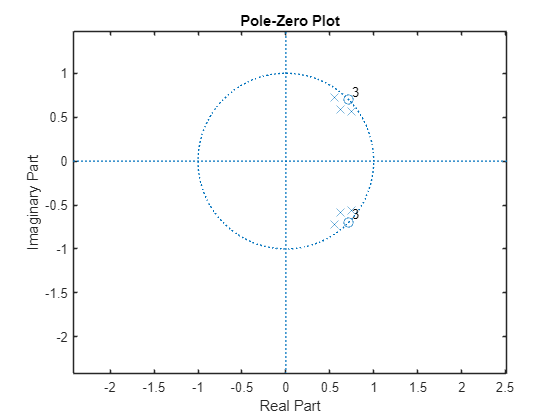

Fs = 8000;
f1 = 800;
f2 = 1200;
w1 = 2*f1/Fs;
w2 = 2*f2/Fs;
[b,a] = butter(3, [w1, w2], 'stop');
zplane(b,a)

The zeros do appear where we expect them to.

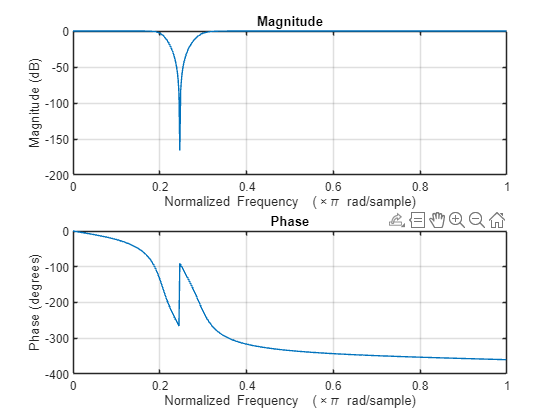

freqz(b,a)

Here we see the magnitude get supressed from .2 to .3 (expected).

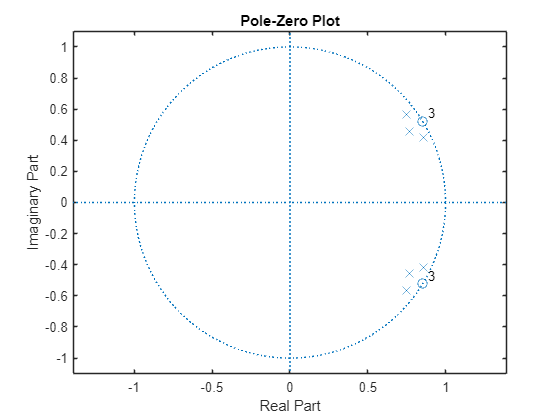

Fs = 11250;
f1 = 800;
f2 = 1200;
w1 = 2*f1/Fs;
w2 = 2*f2/Fs;
[b,a] = butter(3, [w1, w2], 'stop');

zplane(b,a)

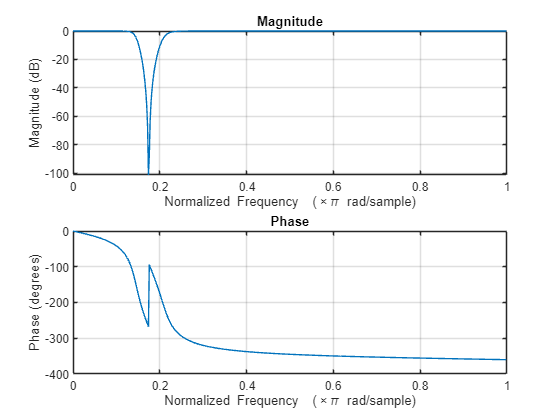


freqz(b,a)

The zeros have shifted closer to angle = 0.

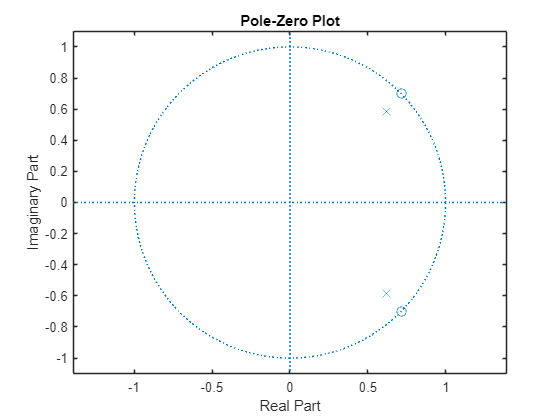

Fs = 8000;
f1 = 800;
f2 = 1200;
w1 = 2*f1/Fs;
w2 = 2*f2/Fs;
[b,a] = butter(1, [w1, w2], 'stop');
zplane(b,a)

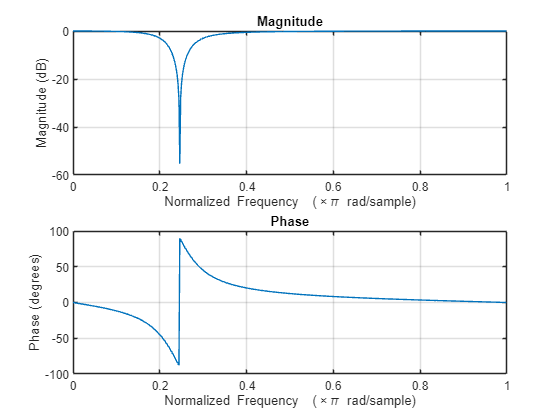

freqz(b,a)

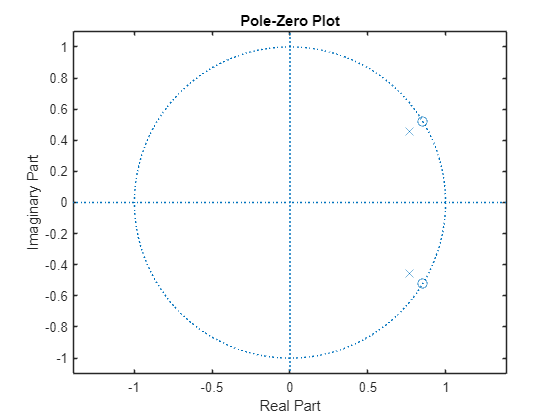


Fs = 11250;
f1 = 800;
f2 = 1200;
w1 = 2*f1/Fs;
w2 = 2*f2/Fs;
[b,a] = butter(1, [w1, w2], 'stop');
zplane(b,a)

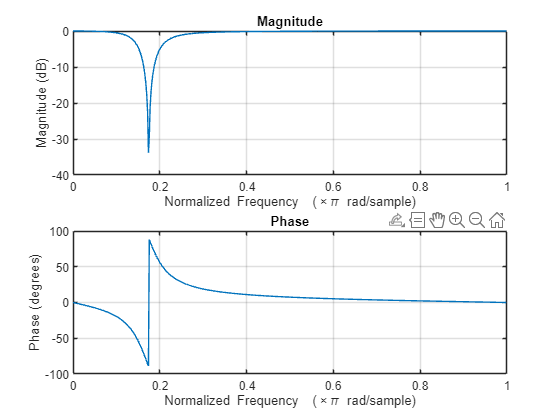

freqz(b,a)

The magnitude drop on the second order filter isn't as severe, nor is the phase difference.

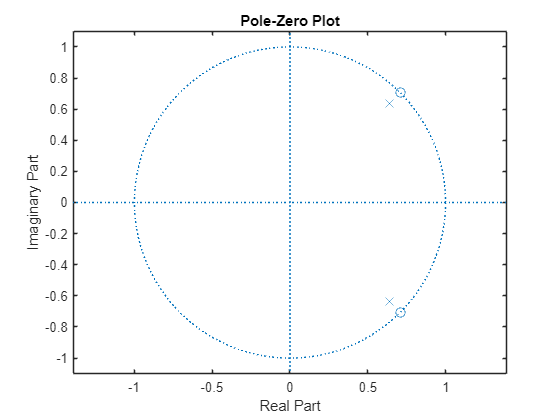

fo=1000;
Fs=8000;
ang=2*pi*fo/Fs;

p = 0.9;
b = [1, -2*cos(ang), 1];
a = [1, -2*p*cos(ang), p^2];
zplane(b, a)

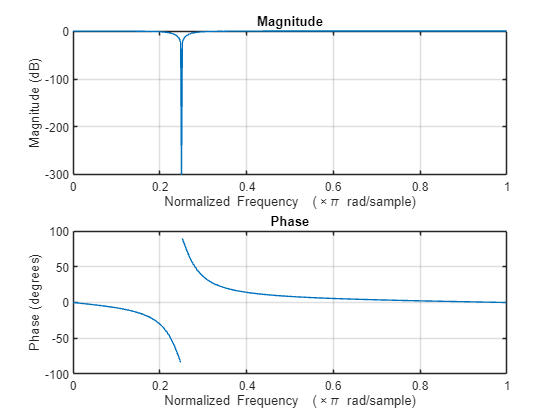

freqz(b, a)

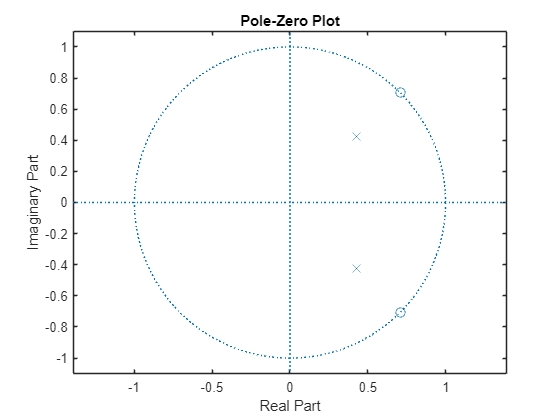


p = 0.6;
b = [1, -2*cos(ang), 1];
a = [1, -2*p*cos(ang), p^2];
zplane(b, a)

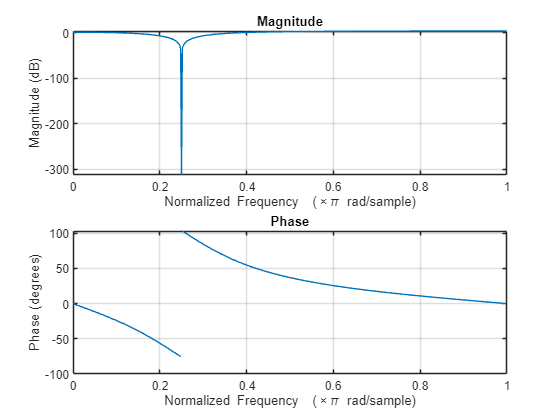

freqz(b, a)

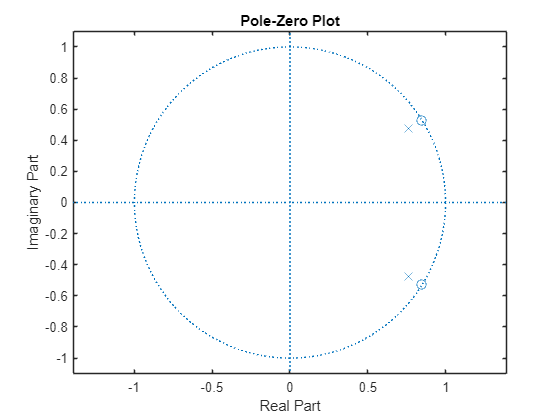


fo=1000;
Fs=11250;
ang=2*pi*fo/Fs;

p = 0.9;
b = [1, -2*cos(ang), 1];
a = [1, -2*p*cos(ang), p^2];
zplane(b, a)

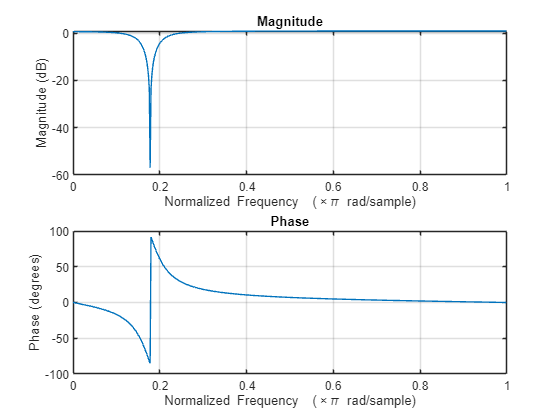

freqz(b, a)

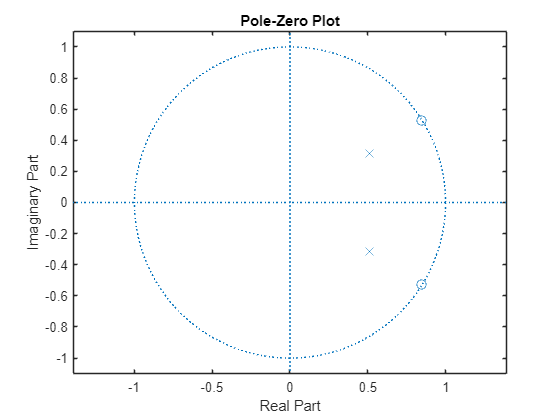


p = 0.6;
b = [1, -2*cos(ang), 1];
a = [1, -2*p*cos(ang), p^2];
zplane(b, a)

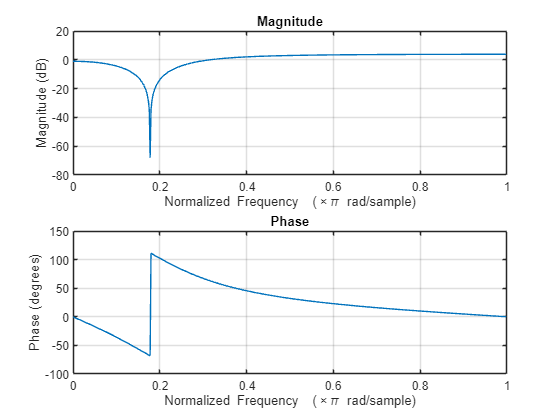

freqz(b, a)

The lower the p, the wider the notch. It also directly controlled how far our poles were from the origin. 

Overall the notch filter provides more precise frequency rejection and the butterworth is more broad. 

I would use the butterworth for a range of frequencies, and the notch to filter a singular frequency.